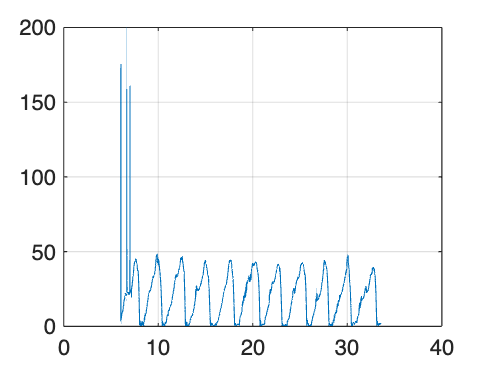

q_tibia = quaternion(data.fem_rot_w, data.fem_rot_x, data.fem_rot_y, data.fem_rot_z);
q_femur = quaternion(data.tib_rot_w, data.tib_rot_x, data.tib_rot_y, data.tib_rot_z);

q_rel = q_tibia .* conj(q_femur);

% Extract the angle in radians
angles = 2 * acos(abs(compact(q_rel(:,1))));

% Convert to degrees if needed
angles_deg = 180 - rad2deg(angles);

plot(data.time, angles_deg(:,1));
hold on;
grid on;